## Metoda Strejca 

load('doc\lab1_wyznaczenie_h.mat')


%został wyznaczony punkt na podstawie wykresu odpowiedzi impulsowej 
y = h;
max_impulse = max(g)

max_impulse = 4.7335e-04

inflection_point_ind = find(g == max_impulse)

inflection_point_ind = 1644

ti = t(inflection_point_ind)

ti = 16.4000


% Oblicz pochodną numeryczną w tym punkcie (wykorzystując różnice skończone)
dt = t(2) - t(1);
dy_dt = gradient(y, dt);

% Oblicz współczynniki stycznej w tym punkcie
% a_tangent = dy_dt(inflection_point_ind)
a_tangent = 0.047

a_tangent = 0.0470

b_tangent = y(inflection_point_ind) - a_tangent * t(inflection_point_ind);
tangent_vec = a_tangent*t + b_tangent

tangent_vec =    -0.4120
   -0.4120
   -0.4119
   -0.4117
   -0.4115
   -0.4110
   -0.4106
   -0.4101
   -0.4096
   -0.4091


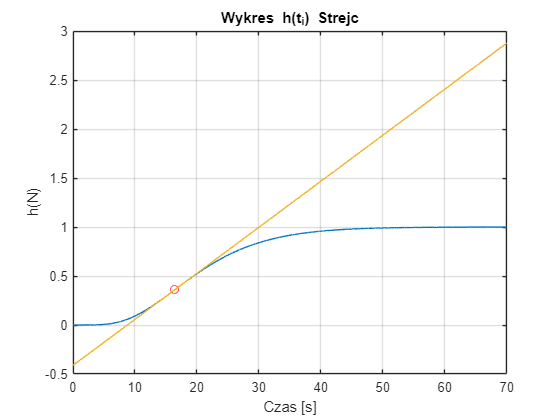

% na początku należy znaleźć punkt przegięcia 
y = h;
figure
plot(t, h)
xlabel('Czas [s]')
ylabel('h(N)')
title('Wykres h(t_i) Strejc')
grid on
hold on
plot(ti, h(inflection_point_ind), 'ro')
plot(t, tangent_vec)
hold off;

## Metoda strejca 2punktowa

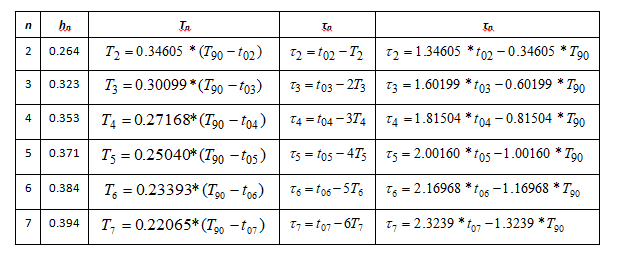

Dla odpowiedzi skokowej obliczonej powyżej należy sprawdzić dopasowanie rządu:

n_vec = 2:7;
h_n = [0.264, 0.323, 0.353, 0.371, 0.384, 0.394];
t_vec = zeros(1,6);
T_vec = zeros(1,6);
T_vec_coef = [0.34605, 0.30009, 0.27168, 0.25040, 0.23393, 0.22065];
tau_vec = zeros(1,6);
G_iter = zeros(1,6);
diff = abs(h - 0.9);
[min_diff, indeks] = min(diff);
T_90 = t(indeks)

T_90 = 33.7000


for iter = 1:6

    diff = abs(h - h_n(iter));
    [min_diff, indeks] = min(diff);
    t_vec(iter) = t(indeks);
    T_vec(iter) = T_vec_coef(iter) * ((T_90) - t_vec(iter));
    tau_vec(iter) = t_vec(iter) - iter*T_vec(iter);
end 
t_vec 

t_vec =    14.3700   15.6400   16.2800   16.6600   16.9300   17.1400


T_vec 

T_vec =     6.6891    5.4196    4.7327    4.2668    3.9230    3.6540


tau_vec

tau_vec =     7.6809    4.8007    2.0820   -0.4073   -2.6850   -4.7838


% for iter = 1:3
%     num = 1;
%     den = [T_vec(iter), 1];
%     G_mul = tf(num, den);
%     G(iter) = tf(num,den,'InputDelay',tau_vec(iter));
%     for i = 1:(n_vec - 1)
%         G(iter) = G(iter) * G_mul
%     end 
% end 

syms s

for iter = 1:3
    num = 1;
    poly = (T_vec(iter) * s + 1)^(iter+1);
    den = sym2poly(poly);
    G(iter) = tf(num, den, 'InputDelay',tau_vec(iter));
end 
G

G =
 
  From input 1 to output:
                            1
  exp(-7.68*s) * -----------------------
                 44.74 s^2 + 13.38 s + 1
 
  From input 2 to output:
                                 1
  exp(-4.8*s) * -----------------------------------
                159.2 s^3 + 88.12 s^2 + 16.26 s + 1
 
  From input 3 to output:
                                       1
  exp(-2.08*s) * ---------------------------------------------
                 501.7 s^4 + 424 s^3 + 134.4 s^2 + 18.93 s + 1
 
Continuous-time transfer function.



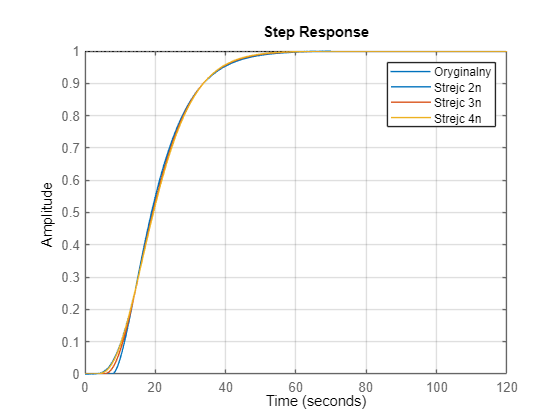

figure;
plot(t, h)
xlabel('Czas [s]')
ylabel('h(N)')
title('Wykres h(t_i) Strejc')
grid on
hold on

for iter = 1:3
    step(G(iter));
end
legend('Oryginalny', 'Strejc 2n', 'Strejc 3n', 'Strejc 4n')
hold off
grid on

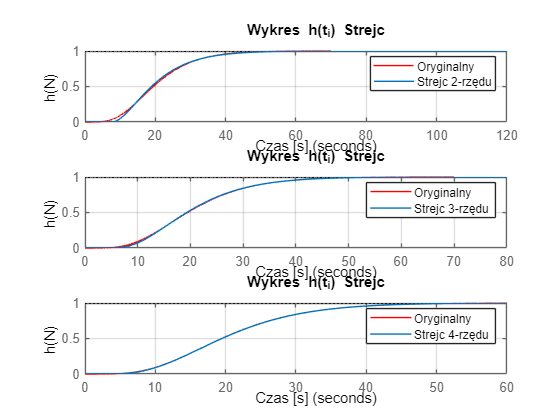

figure
for i = 1:3
    subplot(3, 1, i)
    hold on
    plot(t, h, 'r')
    step(G(i))
    hold off
    xlabel('Czas [s]')
    ylabel('h(N)')
    txt = sprintf('Strejc %d-rzędu', i+1);
    legend('Oryginalny', txt)
    title('Wykres h(t_i) Strejc')
    grid on
end

mean_squared_error = zeros(1, 3);
for i = 1:3
    step_response = step(G(i), 0:0.01:69.99);
    mean_squared_error(i) = sum((step_response - h).^2);
end
mean_squared_error

mean_squared_error =     1.4379    0.2583    0.0055
